data = xlsread('xrayAttenuations.xlsx');

li = data(:, 1:3);
be = data(:, 4:6);
b = data(:, 7:9);
c = data(:, 10:12);

index = li(:,1) < 3e-2;

li = li(index,:);
be = be(index,:);
b =  b(index,:);
c = c(index, :);

rhoLi = 0.534;
rhoBe = 1.84;
rhoB = 2.37;
rhoGraphite = 2.0;
rhoDiamond = 3.51;

energies = li(:,1);
liLengths = 1e4*(rhoLi * li(:,3)).^-1;
beLengths = 1e4*(rhoBe * be(:,3)).^-1;
bLengths = 1e4*(rhoB * b(:,3)).^-1;
graphiteLengths = 1e4*(rhoGraphite * c(:,3)).^-1;
diamondLengths = 1e4*(rhoDiamond * c(:,3)).^-1;

liE = @ (l) 1e3*exp(interp1(log(liLengths), log(energies), log(l)));
beE = @ (l) 1e3*exp(interp1(log(beLengths), log(energies), log(l)));
bE = @ (l) 1e3*exp(interp1(log(bLengths), log(energies), log(l)));
graphiteE = @ (l) 1e3*exp(interp1(log(graphiteLengths), log(energies), log(l)));
diamondE = @ (l) 1e3*exp(interp1(log(diamondLengths), log(energies), log(l)));


[liE(300) liE(1000)]

ans =     1.5288    2.2336


[beE(300) beE(1000)]

ans =     3.1378    4.5741


[bE(300) bE(1000)]

ans =     4.3900    6.4119


[graphiteE(300) graphiteE(1000)]

ans =     5.1836    7.5949


[diamondE(300) diamondE(1000)]

ans =     6.2010    9.0604


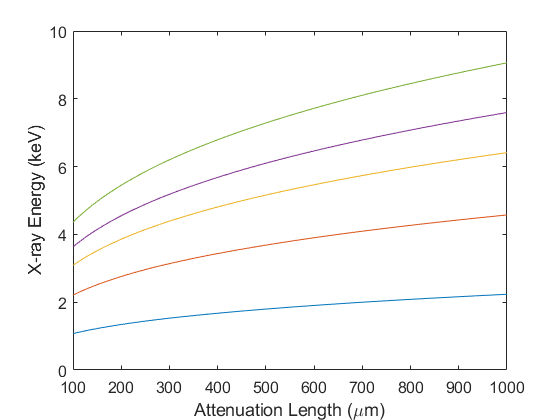



close all
l = 1:1:1000;
plot(l, liE(l)); hold on
plot(l, beE(l)); hold on
plot(l, bE(l)); hold on
plot(l, graphiteE(l)); hold on
plot(l, diamondE(l)); hold on

xlim([100 1000])
ylim([0 10])
xlabel('Attenuation Length (\mum)')
ylabel('X-ray Energy (keV)')
set(gca, 'FontSize', 12)